% Adapted from the Mathworks 
% Biosciences: Statistical Methods Module 
% by Emma Smith Zbarsky

% Load in the penguins data!
filename = "penguins.csv"

filename = "penguins.csv"

penguins = readtable(filename)

penguins = 344×7 table
     species         island        bill_length_mm    bill_depth_mm    flipper_length_mm    body_mass_g       sex    
    __________    _____________    ______________    _____________    _________________    ___________    __________

    {'Adelie'}    {'Torgersen'}         39.1             18.7                181              3750        {'MALE'  }
    {'Adelie'}    {'Torgersen'}         39.5             17.4                186              3800        {'FEMALE'}
    {'Adelie'}    {'Torgersen'}         40.3               18                195              3250        {'FEMALE'}
    {'Adelie'}    {'Torgersen'}          NaN              NaN                NaN               NaN        {0×0 char}
    {'Adelie'}    {'Torgersen'}     

% Make the variables into arrays for easy access
% Fill in the blanks '%%%%' by indexing the corresponding columns
% in the table
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);

% Clean up the data using 'Data Cleaner' in the Apps tab!
% Clean all the variables in 'Clean Missing Data' -> 'Table Variables' ->
% three dots -> Select all
% Export a new, cleaned-up version of the table as 'penguins1'

% Display/show the new table penguins 1:
penguins1

penguins1 = 333×7 table
    species     island      bill_length_mm    bill_depth_mm    flipper_length_mm    body_mass_g     sex  
    _______    _________    ______________    _____________    _________________    ___________    ______

    Adelie     Torgersen         39.1             18.7                181              3750        MALE  
    Adelie     Torgersen         39.5             17.4                186              3800        FEMALE
    Adelie     Torgersen         40.3               18                195              3250        FEMALE
    Adelie     Torgersen         36.7             19.3                193              3450        FEMALE
    Adelie     Torgersen         39.3             20.6                190              3650        MA

% How many penguins did we lose in cleaning this data?
% (hint: try size())
size(penguins1)

ans =    333     7


size(penguins)

ans =    344     7


% We seem to have lost 11 data points

% We can separate the data by species:
gentoo = penguins1(penguins1.species == "Gentoo",:); 
% Do the same thing for Chinstrap penguins below:
chinstrap = penguins1(penguins1.species == "Chinstrap",:); 

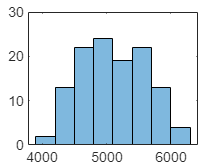

% We can make a histogram of the body mass distribution!
% For the Gentoo penguins:
figure()
w(1) = histogram(gentoo.body_mass_g, "FaceAlpha", 0.5, SeriesIndex=1); % the "w(1)" just makes the histogram an object stored in the workplace
hold on % hold on/off helps add new plots to an existing set of axes instead of tons of new figures

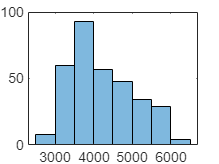

w =   1×3 Histogram array:

    Histogram    Histogram    Histogram


% Use the built-in function histogram() to plot:
% a) a histogram of ALL the penguins' body mass distribution
% b) a histogram of just the Chinstrap penguins' body mass (use SeriesIndex = 2 for color)
w(2) = histogram(penguins1.body_mass_g, "FaceAlpha", 0.5)

w(3) = histogram(chinstrap.body_mass_g, "FaceAlpha", 0.5, SeriesIndex=2)

w =   1×3 Histogram array:

    Histogram    Histogram    Histogram


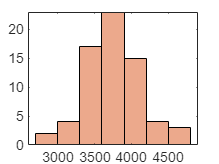

hold off

## Linear Regression!

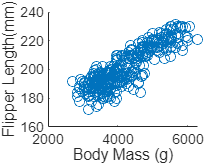

% Use scatter() to create a scatter plot of body mass on the x-axis,
% and flipper length on the y-axis
% (hint: the first input is penguins1.body_mass_g)
scatter(penguins1.body_mass_g, penguins1.flipper_length_mm)
ylabel("Flipper Length(mm)")
xlabel("Body Mass (g)")

% Use fit()to fit a model!
% "poly1" is for a linear regression; there are many other options too
% Calculate a line of best fit for the data above:
% linear_model = fit(x, y, "poly1")
% (hint: x and y are the variables in the prev block)
linear_model = fit(penguins1.body_mass_g, penguins1.flipper_length_mm,"poly1")

linear_model =      Linear model Poly1:
     linear_model(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.0152  (0.01428, 0.01611)
       p2 =         137  (133.1, 141)

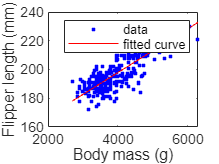

% Plot the line of best fit on the data using plot():
% plot(linear_model, x, y)
% and add xlabel and ylabel as well!
plot(linear_model, penguins1.body_mass_g, penguins1.flipper_length_mm)
xlabel("Body mass (g)")
ylabel("Flipper length (mm)")

% You can also ask fit() to output the goodness of fit
% by specifiying an extra output:
% [linear_model, gof] = fit(x, y, "poly1")
% Try it for the data above!
[linear_model, gof] = fit(penguins1.body_mass_g, penguins1.flipper_length_mm,"poly1")

linear_model =      Linear model Poly1:
     linear_model(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.0152  (0.01428, 0.01611)
       p2 =         137  (133.1, 141)

gof = struct with fields:
           sse: 1.5516e+04
       rsquare: 0.7621
           dfe: 331
    adjrsquare: 0.7614
          rmse: 6.8466


% Look up the types of fits for the fit()
% function and try another model, like "poly2"
% on the same data
